# Create Logarithmic Axis Plots

`loglog` plots *x* and *y *coordinates using a base 10 logarithmic scale on the *x*-axis and the *y*-axis.

### Define Exponential Data to Plot

Define `x` as a vector of 50 logarithmically spaced numbers on the interval $\left\lbrack {10}^{-1} ,{10}^2 \right\rbrack \;$using the `logspace` function. Define `y` as the exponential function $2^x$.

x = logspace(-1,2);
y = 2.^x;

### Basic Log Plot

Call the `loglog` function which will generate a scaled figure with logarithmic axes.

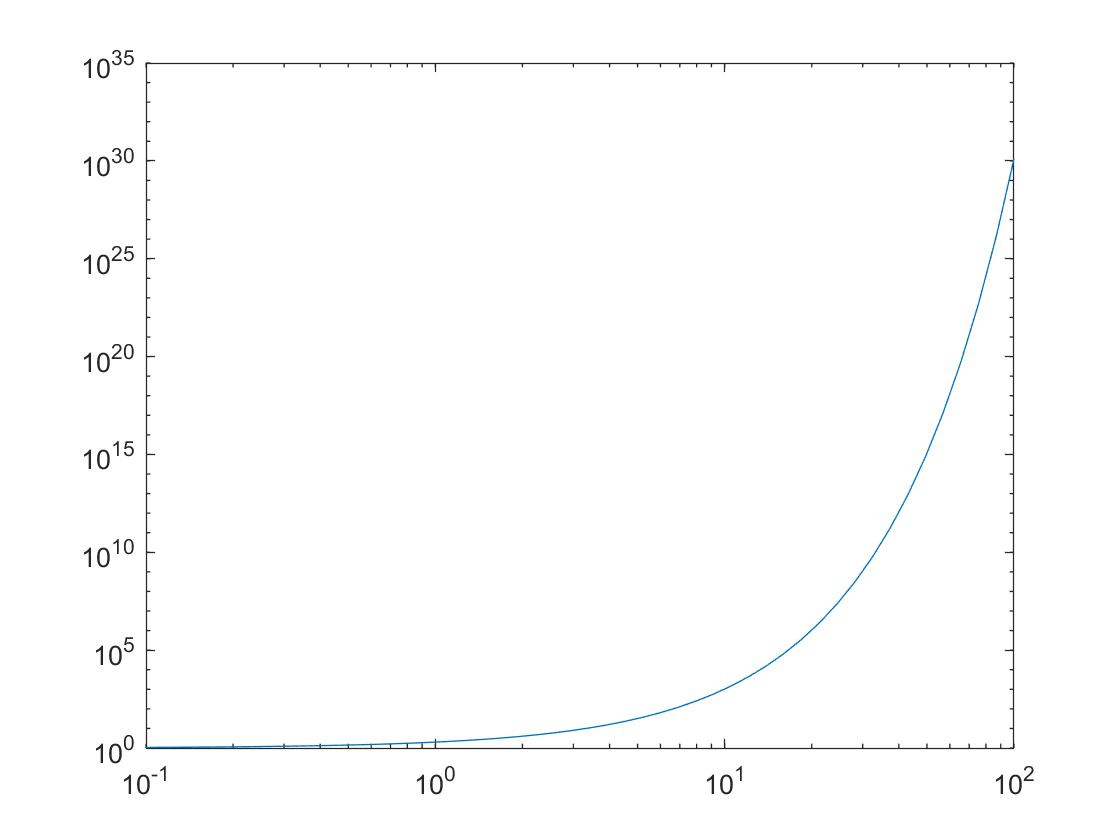

loglog(x,y)

## Customizations

### Plot Points and Specify Colors

The line properties can be adjusted depending on how you wish to visualize the data. If a point marker is desired, specify the single point type as a function input. The point color can be specified by the *MarkerEdgeColor *property.

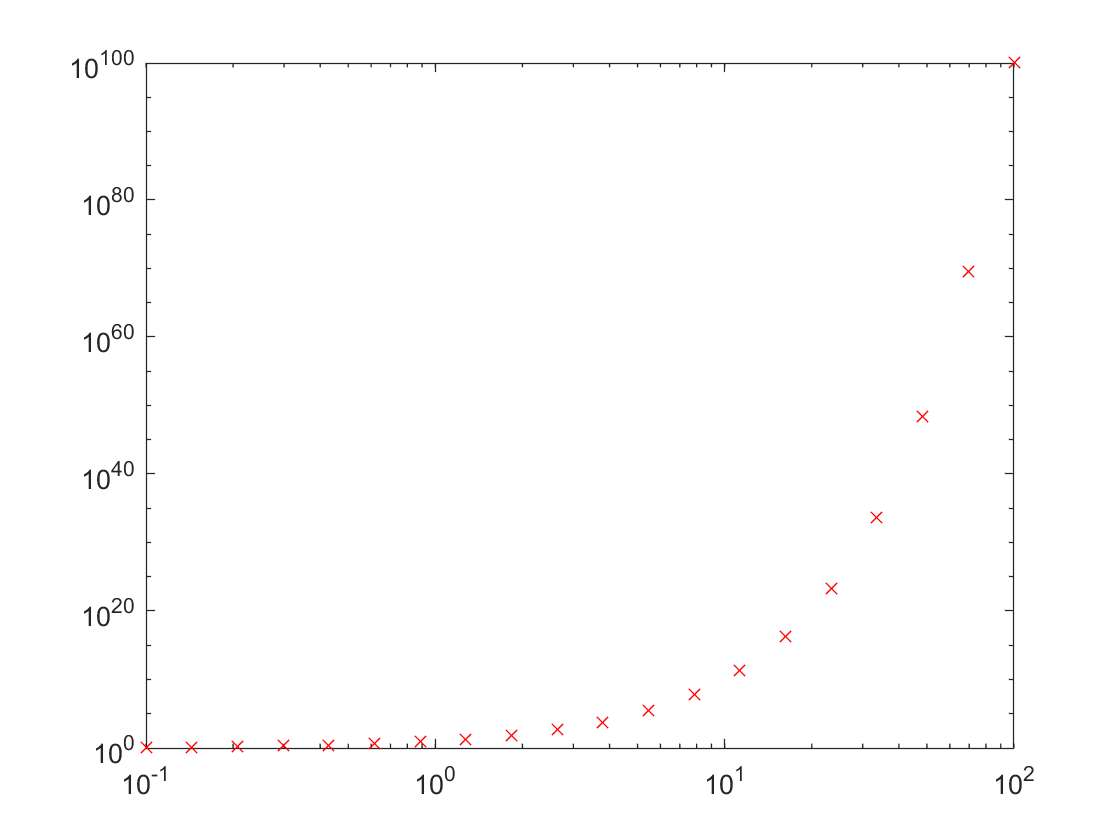

x = logspace(-1,2,20);
y = 10.^x;
MarkerType = 'x';
MarkerFaceColor = 'r';
loglog(x,y,...
    MarkerType,...                              % Specify the point type as an imput preceding the data
    "MarkerEdgeColor", MarkerFaceColor);        % Specify the point color 

### Plot Two Data Sets With Different Line Styles

Create two mirrored sets of data to plot and pass them both as consecutive inputs to the loglog function. To adjust the style of a single line, provide the line style identifier as an input following the data for that line. To adjust the line style of both, the *LineStyle *style property can be specified as a name-value pair.

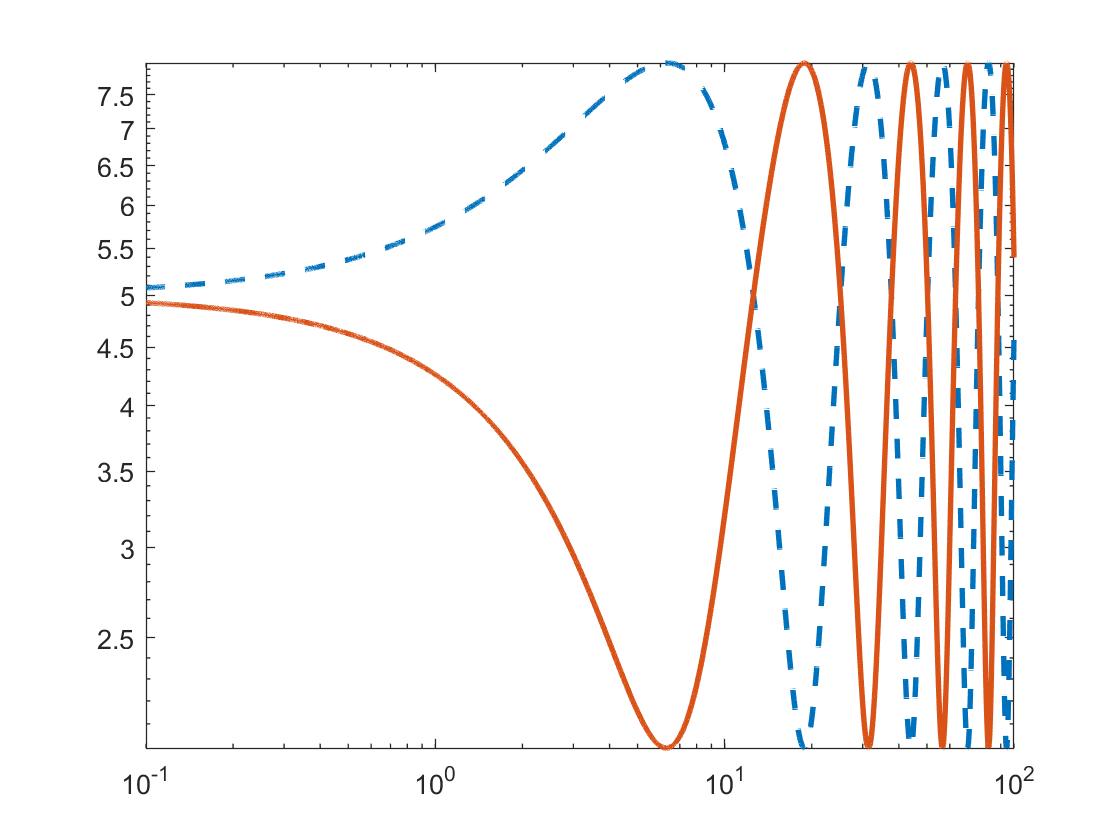

LineType = '--';
x = logspace(-1,2,10000);
y1 = 5 + 3*sin(x/4);
y2 = 5 - 3*sin(x/4);
figure
lg = loglog(x,y1,LineType,...               % plot the first data set and specify its line type
    x,y2,...                                % plot the second data set 
    "LineWidth",2);                         % specify the line thickness for both plots

### Customize Axes

Add a label to the `y` axis and specify axis scaling using the `ytick` feature to position tick marks at defined integer values.

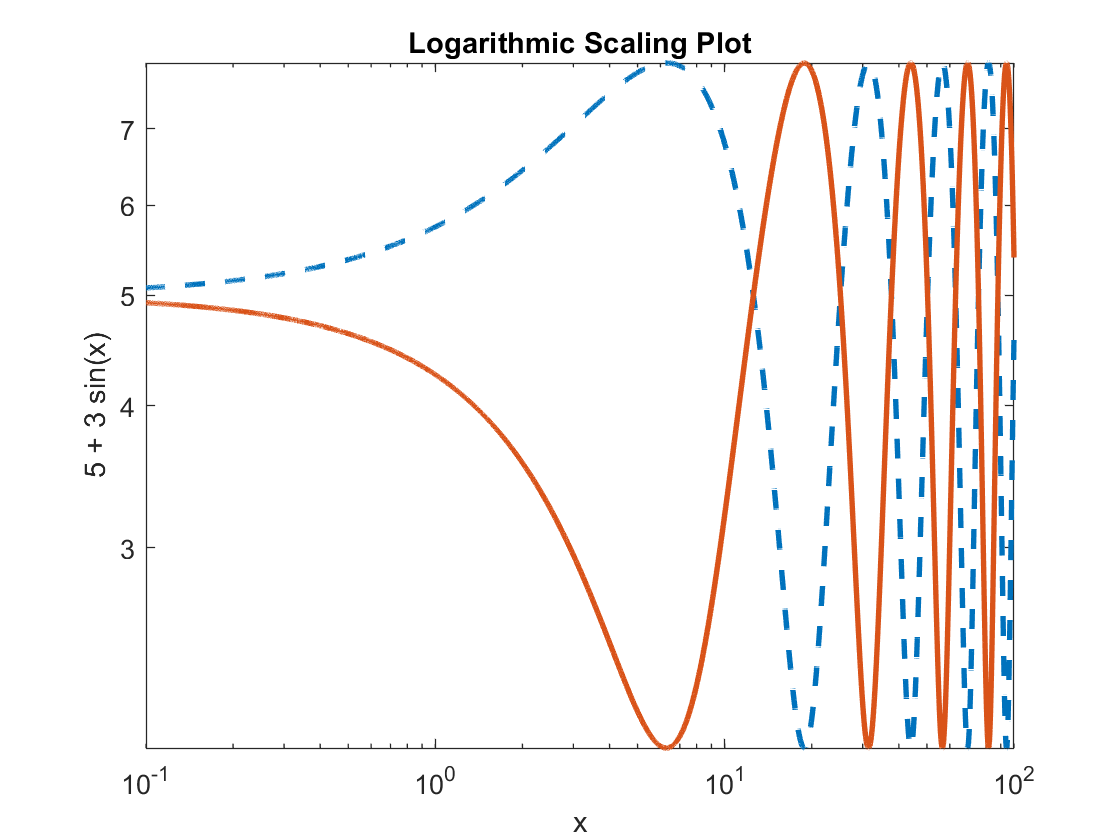

yticks([3 4 5 6 7])
xlabel("x")
ylabel("5 + 3 sin(x)")
title("Logarithmic Scaling Plot")

## Additional Information

### Get All Loglog Properties

Graphics objects in MATLAB have many properties. To see all the properties of a loglog, uncomment the following code

% get(lg(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[loglog](https://www.mathworks.com/help/matlab/ref/loglog.html)